- (unchecked)

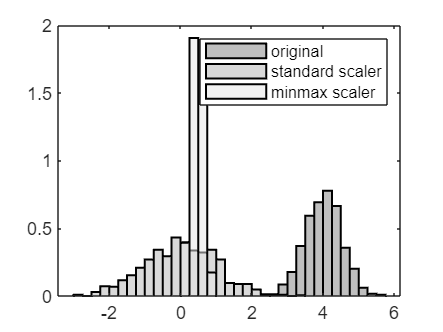

x = 0.5*randn(1000,1) + 4;
y = (x - mean(x)) / std(x);
z = (x - min(x)) / (max(x) - min(x));

figure;
histogram(x, 'BinMethod', 'Scott', 'Normalization', 'pdf', 'DisplayStyle', 'bar', 'EdgeColor', 'k', 'FaceColor', [0.5 0.5 0.5], 'FaceAlpha', 0.5, 'LineWidth', 1, 'BinWidth', 0.25, 'EdgeAlpha', 1, 'DisplayName', 'original');
hold on;
histogram(y, 'BinMethod', 'Scott', 'Normalization', 'pdf', 'DisplayStyle', 'bar', 'EdgeColor', 'k', 'FaceColor', [0.7 0.7 0.7], 'FaceAlpha', 0.5, 'LineWidth', 1, 'BinWidth', 0.25, 'EdgeAlpha', 1, 'DisplayName', 'standard scaler');
histogram(z, 'BinMethod', 'Scott', 'Normalization', 'pdf', 'DisplayStyle', 'bar', 'EdgeColor', 'k', 'FaceColor', [0.9 0.9 0.9], 'FaceAlpha', 0.5, 'LineWidth', 1, 'BinWidth', 0.25, 'EdgeAlpha', 1, 'DisplayName', 'minmax scaler');
legend('show');

2. (unchecked)

data = readtable('http://apmonitor.com/pds/uploads/Main/tclab_data6.txt');
data = table2timetable(data);

Error using table2timetable
Input table must contain datetime or duration vector for row times.

data.Time = datetime(data.Time,'ConvertFrom','datenum');
data = retime(data,data.Time);

% Split into train and test subsets (20% for test)
trainIndex = floor(0.8 * height(data));
train = data(1:trainIndex,:);
test = data(trainIndex+1:end,:);

3. (unchecked)

% Standardize train data
s = zscore(train{:,:});
s_train = table(s);

4. unchecked

% Print scale
disp('a: ');
disp(s.scale_);

% Print mean
disp('b: ');
disp(s.mean_);

5. unchecked

% Standardize test data
s_test = (test{:,:} - s.mean_) ./ s.scale_;
s_test = table(s_test);

6. unchecked

s_train_df = array2table(s_train, 'VariableNames', train.Properties.VariableNames);
s_test_df = array2table(s_test, 'VariableNames', test.Properties.VariableNames);

7. unchecked

% convert scaled values back to dataframe
s_train_df = pd.DataFrame(s_train, columns=train.columns.values);
s_test_df = pd.DataFrame(s_test, columns=test.columns.values);

8. unchecked, wrong?

Scaler multipliers
a: [0.11595824 0.11032197]
Scaler minimum
b: [18.85444444 31.69677778]

9. unchecked

x = s.inverse_transform(s_test);

10. unchecked

data = readtable('http://apmonitor.com/pds/uploads/Main/tclab_data6.txt');
data = table2timetable(data);
data.Time = datetime(data.Time,'InputFormat','yyyy-MM-dd''T''HH:mm:ss.SSSSSS');
histogram(data.Variables,30,'Alpha',0.7,'DisplayStyle','stairs','LineWidth',1);
datetick('x','keeplimits');

11. unchecked

X = data;
X_scaled = (X-mean(X))./std(X);
histogram(X_scaled,10,'Alpha',0.7,'DisplayStyle','stairs','LineWidth',1);

12. unchecked

rng(0,'twister');
X = sdata;
p = 0.8;
cvp = cvpartition(size(X,1),'HoldOut',p);
X_train = X(training(cvp),:);
X_test = X(test(cvp),:);

% create neural network
hiddenLayerSize = [3 3];
net = fitnet(hiddenLayerSize,'trainlm');
[net,tr] = train(net,X_train(:,[1 2]),X_train(:,3));

% test neural network
X_test_predict = net(X_test(:,[1 2]));

% unscale data
X_test = s.inverse_transform(X_test);
X_test_predict = s.inverse_transform(X_test_predict');

% plot results
scatter(X_test(:,3),X_test_predict(:,3))
hold on
plot([15 28],[15 28],'r-')
xlabel('T2')
ylabel('T2p')
hold off
saveas(gcf,'results.png')

13. unchecked

data = readtable('http://apmonitor.com/pds/uploads/Main/tclab_data6.txt');

p = 0.8;
cvp = cvpartition(height(data),'HoldOut',p);
train = data(training(cvp),:);
test = data(test(cvp),:);

% train neural network
hiddenLayerSize = [3 3];
net = fitnet(hiddenLayerSize,'trainlm');
[net,tr] = train(net,table2array(train(:,[2 3])),table2array(train(:,4)));

% test neural network
test.T2p = predict(net,table2array(test(:,[2 3])))

% plot results
scatter(table2array(test(:,4)),table2array(test(:,5)))
hold on
plot([15 28],[15 28],'r-')
xlabel('T2')
ylabel('T2p')
hold off
